# Tutorial: Workflow "Simulate + Plot"

In this tutorial, we'll do a first simulation with a PBPK model. 

First we define an observable:

obs = PBPKobservables();

Then we will create a virtual individual, that is, an object of class "Individual" to be used for simulation:

indv = Individual('Virtual')

indv = 	Individual object:

          type: 'Virtual individual'
          name: []
        dosing: '0 dosing events'
    physiology: '0 parameters defined'
      drugdata: '0 parameters defined'

Use builtin('disp',OBJ)) to see the underlying structure of the Individual object OBJ

You can see that the components of the Individual object are empty. Let's give it a name:

indv.name = 'First simulation';

We add a reference physiology from the physiology database:

indv.physiology = Physiology('human35m');

 a one-hour iv infusion of 60 milligrams Amitriptyline:

indv.dosing = Infusion('Amitriptyline', 0*u.h, 60*u.mg, 1*u.h, 'iv');

a 24-hour observation sampling window

indv.sampling = Sampling([0 24]*u.h, obs);

Then, we load drug data for Amitriptyline in humans: 

indv.drugdata   = loaddrugdata('Amitriptyline','species','human');

We will use a standard 12-compartment PBPK model for small-molecule drugs, the well-stirred tissue distribution model.

indv.model  = sMD_PBPK_12CMT_wellstirred;

This model requires, as a model option, a prediction method for tissue partitioning. We will use the Rodgers & Rowland method.

indv.model.options.tissuePartitioning = @rodgersrowland;

Looking at the Individual object again, you can now see a summary of the defined building blocks, and in particular, the uninitialized PBPK model. This means that the model parameters and initial conditions have not yet been computed from the dosing scheme, physiological characteristics and drug properties.

indv

indv = 	Individual object:

          type: 'Virtual individual'
          name: 'First simulation'
        dosing: '1 Infusion event(s)'
    physiology: '35 parameters defined'
      sampling: 'timespan 0 h - 24 h with 11 observables'
      drugdata: '12 parameters defined'

Use builtin('disp',OBJ)) to see the underlying structure of the Individual object OBJ

Once the initialize function is called

initialize(indv)

the Individual object is updated to "initialized".

Next, we call function 'simulate' to solve the ODEs corresponding to the 12-compartment PBPK model. The result is assigned into the `observation` property:

simulate(indv)

Finally, we can plot the model predictions. Calling function `plot()` with a simulated `Individual` object produces the default toolbox plots. 

These plots can be customized at different levels, which is the topic of another tutorial. We only use one simple customization here, setting a reasonable unit for the simulated concentrations instead of the default kg per cubic meters.

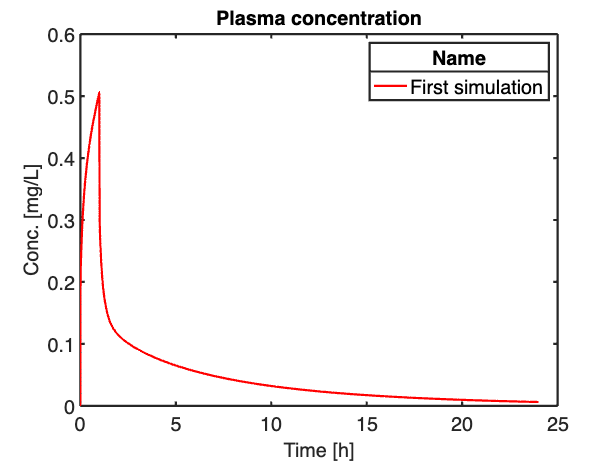

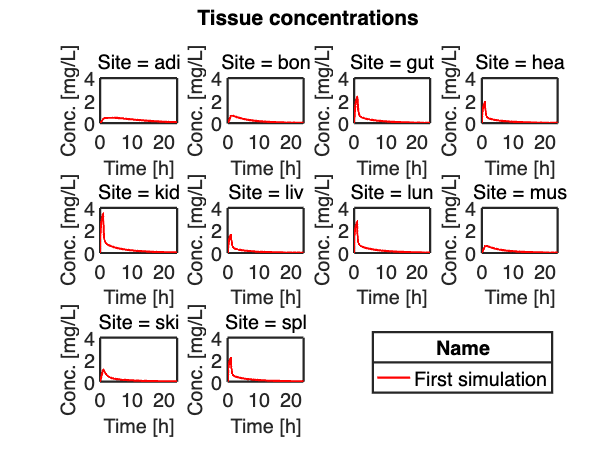

plot(indv,'yunit','mg/L')

Two windows appear: a plot with plasma concentrations and a plot with tissue concentrations.

You now know how to do a simulation task with the MATLAB PBPK toolbox!